# Three-Link Planar (Forward and inverse kinematics)

## **prerequisites:**

- Installation of Robotics toolbox Version 10.4 by Peter Corke [https://petercorke.com/toolboxes/robotics-toolbox/](https://petercorke.com/toolboxes/robotics-toolbox/)

- Familiar with basics of kinematics and Matlab

- Reference reading: Chapter 2&3 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

## Objectives:

- Formulate and simulate forward and inverse kinematics of three-link planar arm

- Differential Kinematics of three-link planar arm

- Velocity Profile of three-link planar arm

- Resolved rate motion control of three-link planar arm

clear; 
clc;

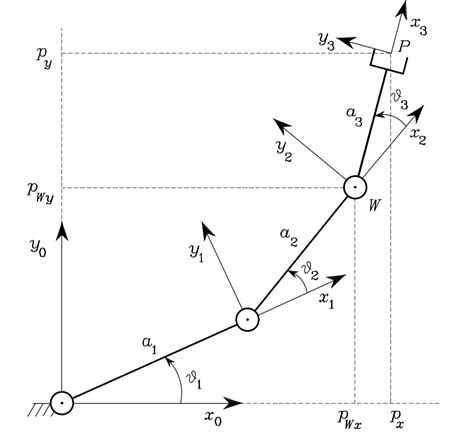

**DH parameters:**

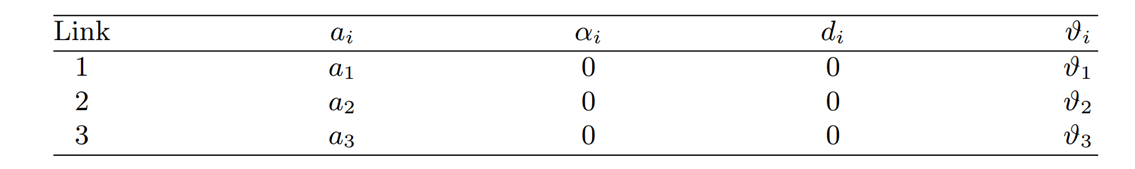

### Task Space: $\left(x,y,\alpha \right)\in \mathrm{SO}\left(2\right)\;\mathrm{where}\;\alpha =\theta_1 +\theta_2 +\theta_3$ 

### Configuration Space: $\left(q_1 ,q_2 ,q_3 \right)$ 

## Forward Kinematics

Homogenous Transform

syms q1 q2 q3 a1 a2 a3
E = trchain2('R(q1) Tx(a1) R(q2) Tx(a2) R(q3) Tx(a3)',[q1,q2,q3]);
E = simplify(E)

$$E = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)+a_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)+a_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 1 \end{array}\right)$$

Create a robot model using Robotics toolbox from DH parameters

a1 = 1; a2 = 0.7; a3=0.5; 
p3 = SerialLink([
    Revolute('d', 0, 'a', a1, 'alpha', 0, 'standard')
    Revolute('d', 0, 'a', a2, 'alpha', 0, 'standard')
    Revolute('d', 0, 'a', a3, 'alpha', 0, 'standard')
    ], ...
    'name', 'planar 3 link');
p3

 
p3 = 
 
planar 3 link:: 3 axis, RRR, stdDH, slowRNE                      
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|        0.7|          0|          0|
|  3|         q3|          0|        0.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


If required: Update base and end effector transforms: $T_e^b =T_0^b *T_N^0 *T_e^N$ 

p3.base = transl(0,0,0)*trotx(0);
p3.tool = transl(0,0,0);

robot = struct with fields:
    base: [4×4 double]
    tool: [4×4 double]


## Inverse Kinematics 

### Closed Form Inverse Kinematics 

**Specify Target Pose**

% Target Position and alpha angle (x,y,alpha)
X = 0; Y = 2.2; alpha = pi/2;
T = transl(X,Y,0) * rpy2tr(0,0,rad2deg(alpha),'degree')

T =          0   -1.0000         0         0
    1.0000         0         0    2.2000
         0         0    1.0000         0
         0         0         0    1.0000


**Calculate joint angles analytically**

Xw = X-a3*cos(alpha);
Yw = Y-a3*sin(alpha);
c2 = (Xw^2+Yw^2-a1^2-a2^2)/(2*a1*a2); 
if (vpa(c2,2)>1.00)
    fprintf("Warning: c2 is greater than 1 >> most likely out of reach");
end
s2 = real(sqrt(1-c2*c2));
s1 = ((a1 + a2*c2)*Yw - a2*s2*Xw)/(Xw^2+Yw^2);
c1 = ((a1 + a2*c2)*Xw + a2*s2*Yw)/(Xw^2+Yw^2);

theta1 = atan2(s1,c1);
theta2 = atan2(s2,c2);
theta3 = alpha-theta2-theta1;
q_an = [theta1 theta2 theta3]

q_an =     1.5708         0   -0.0000


**Notes: **

- When s2=0; theta2 = 0, pi >>> the manipulator is at a kinematic *singularity*.   

- theta1 can be determined uniquely, unless *a*1 = *a*2  

- if c2>1, no solution can be found (complex numbers)

- (X,Y,alpha) = (0,a1+a2+a3,pi/2) may result in s2 being a complex number due to rounding errors

### Numerical Inverse Kinematics 

**Calculate joint angles numerically with intial guesses**

q_num = p3.ikine(T,[X Y alpha], 'mask',[1 1 0 0 0 1])

### **Validate IK solution with FK:**

% analytical
x_an = p3.fkine(q_an)

 

x_an = 
         0        -1         0         0
         1         0         0       2.2
         0         0         1         0
         0         0         0         1


% numerical
x_num = p3.fkine(q_num)

 

x_num = 
         0        -1         0         0
         1         0         0       2.2
         0         0         1         0
         0         0         0         1


**Plotting Analytical solution**

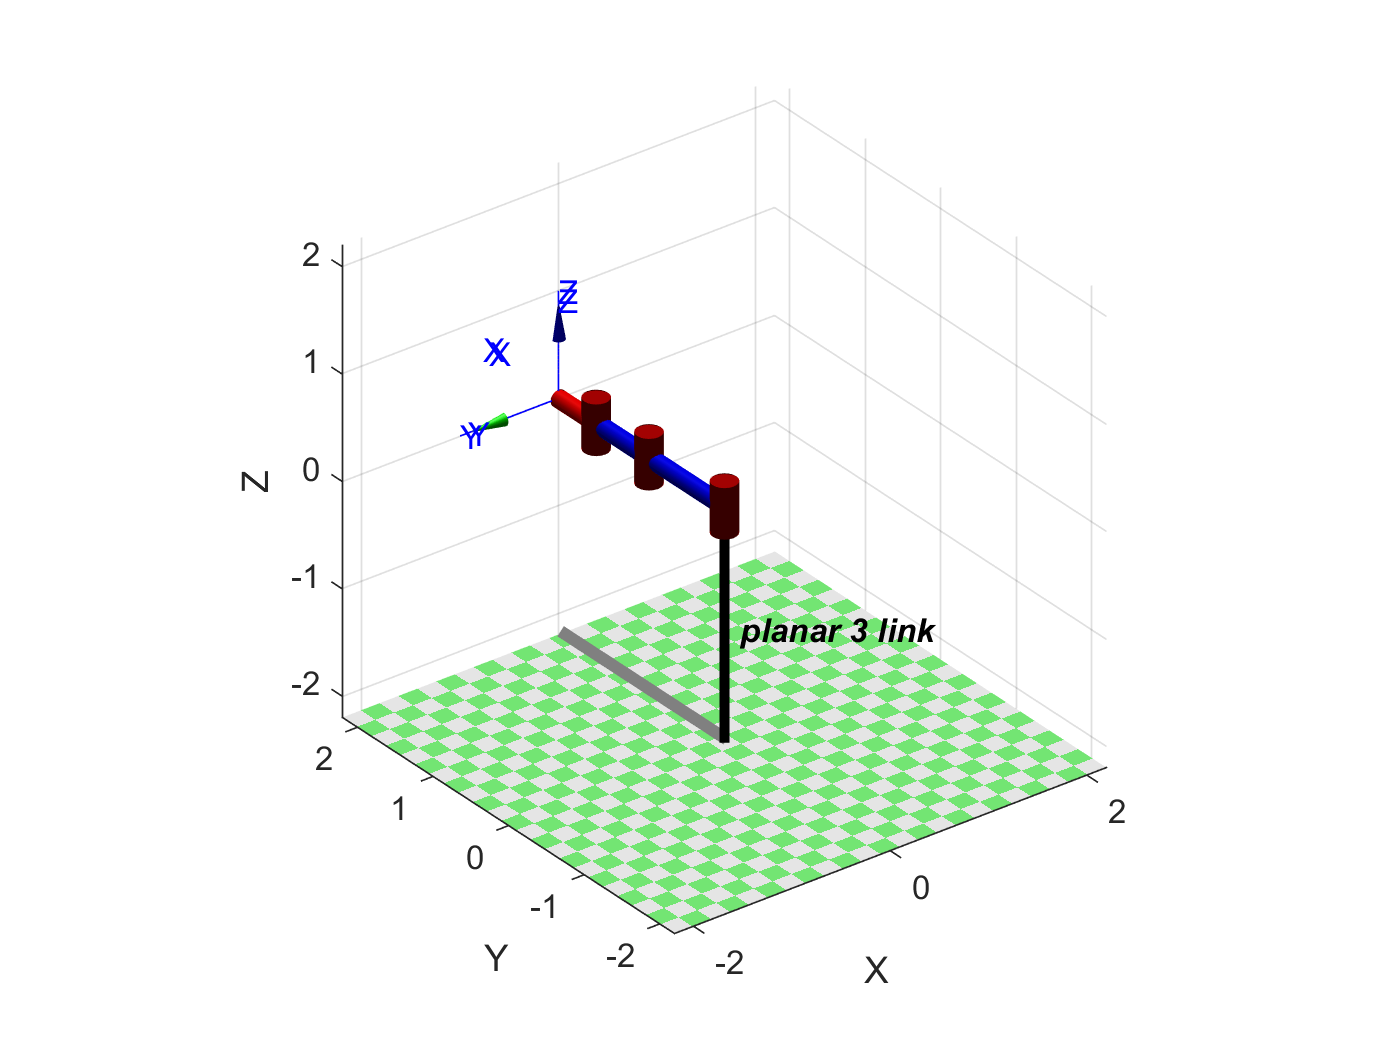

figure(Name="Analytical");
p3.plot(q_an); hold on; trplot(T); hold off; % target Pose

**Plotting Numerical solution**

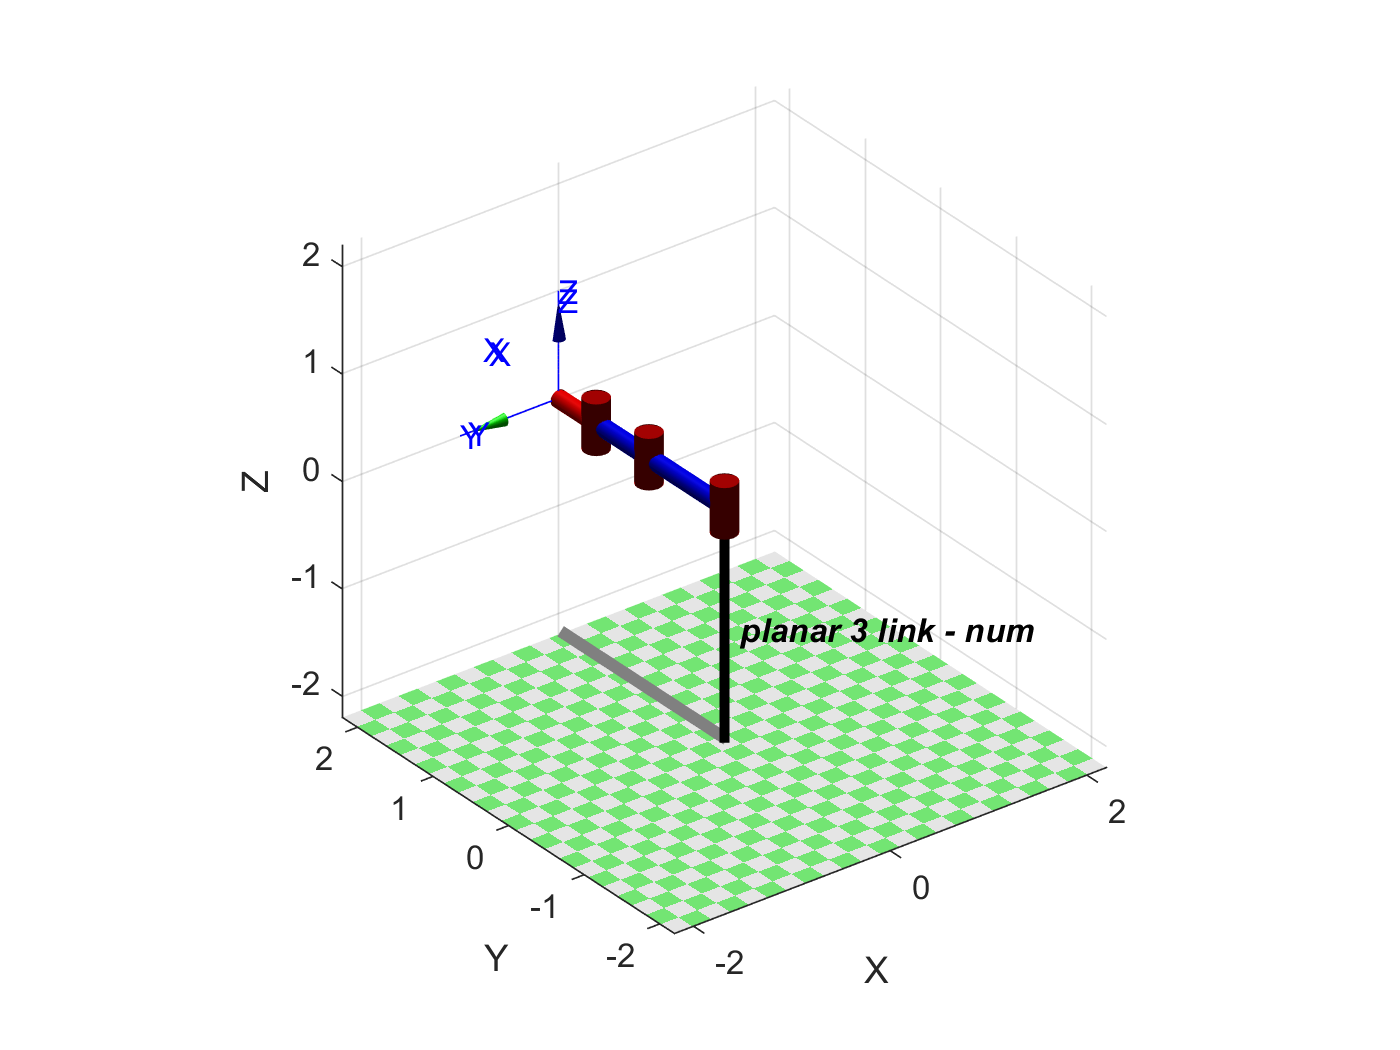

figure(Name="Numerical");
p3_num = p3;
p3_num.name = 'planar 3 link - num';
p3_num.plot(q_num); hold on; trplot(T); % target Pose
hold off;

## Differential Kinematics

### Geometric Jacobian

q = [0,0,pi/2];
J = p3.jacobe(q)

J =     1.7000    0.7000         0
    0.5000    0.5000    0.5000
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


### `Singularity`

`displays the linear dependency of joints in a Jacobian matrix.`

jsingu(J)

1 linearly dependent joints:
  q3 depends on: q1 q2 


### Velocity profile (Elipse) and Singularities 

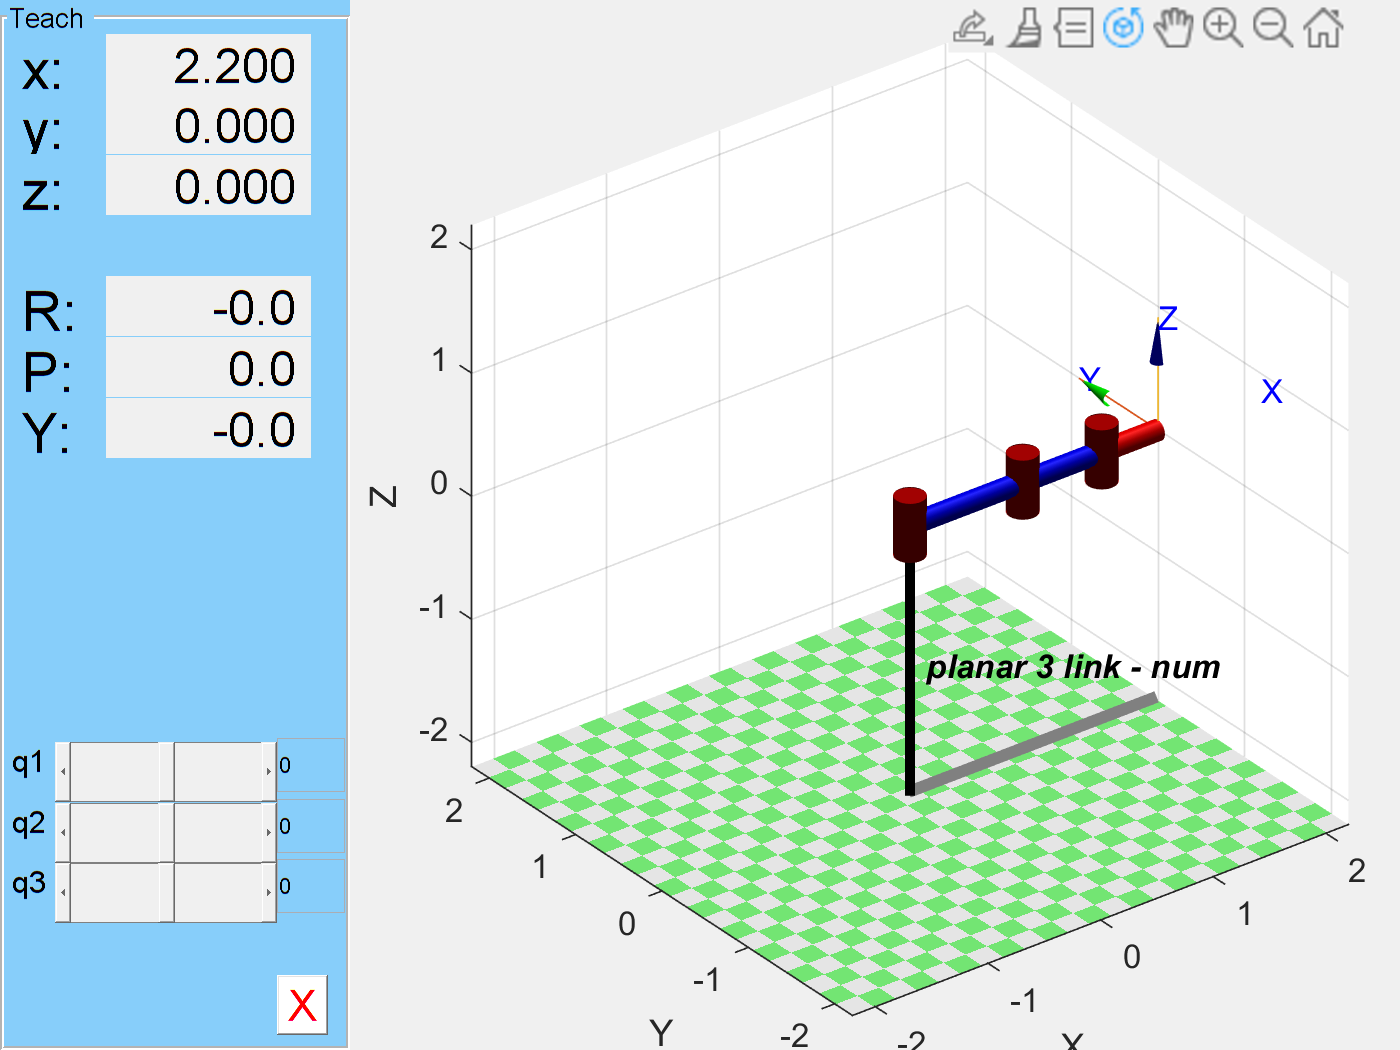

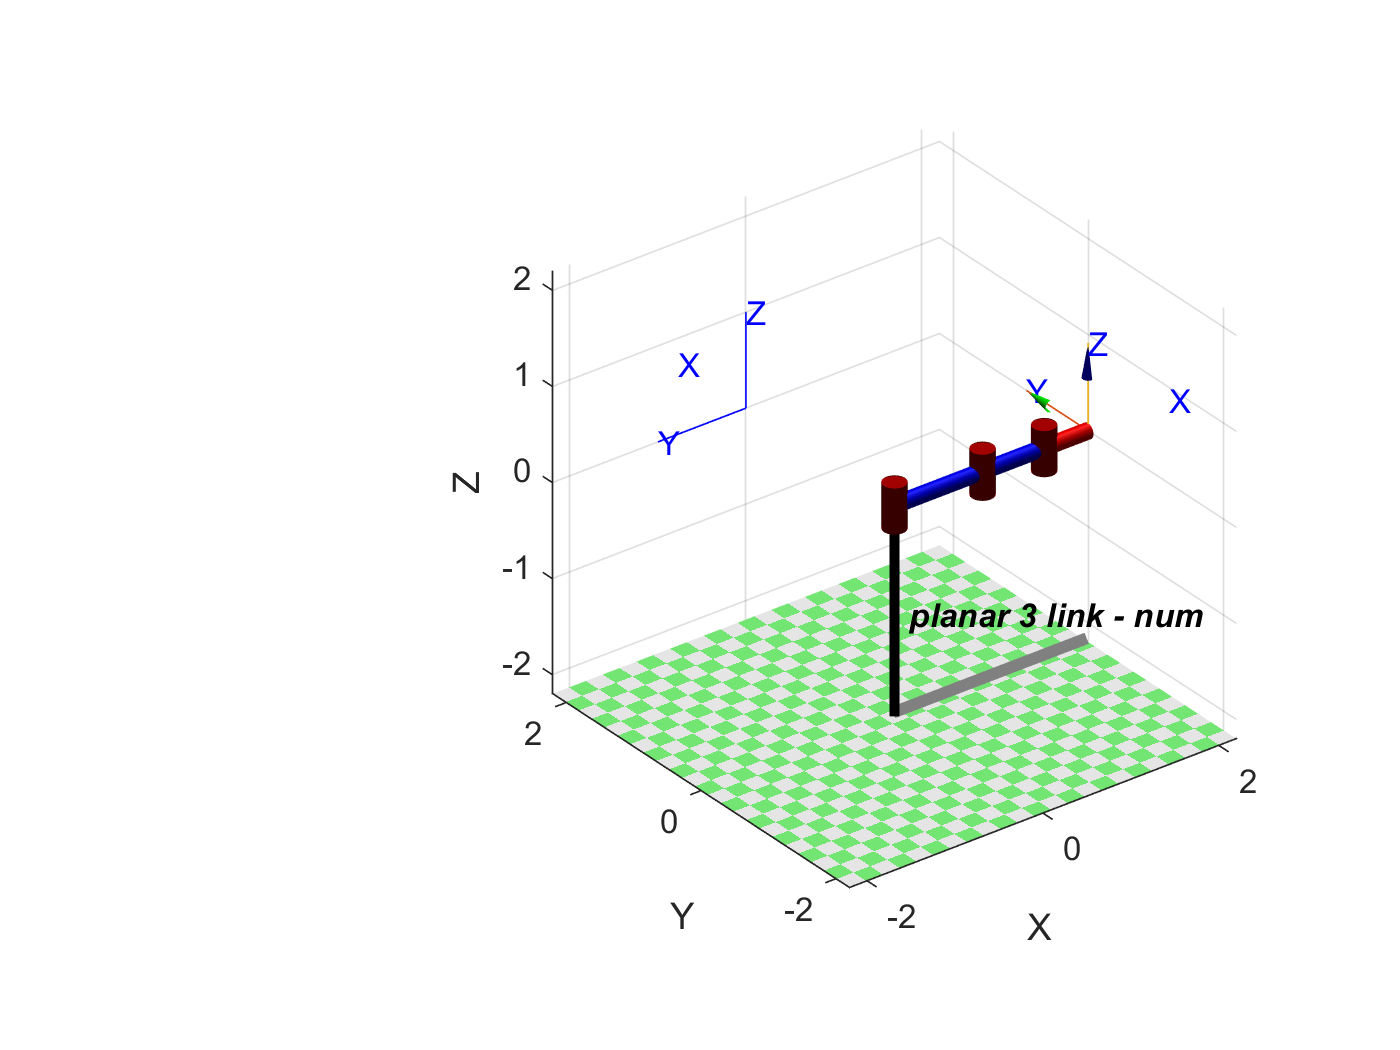

q = [pi/2,-pi/2,0];
figure(1)
set(gcf,'Visible','on')
p3.teach('callback', @(r,q) r.vellipse(q,'2d'))

## Resolved-rate motion control

Controlling the end-effector velocity through the Jacobian without inverse kinematics

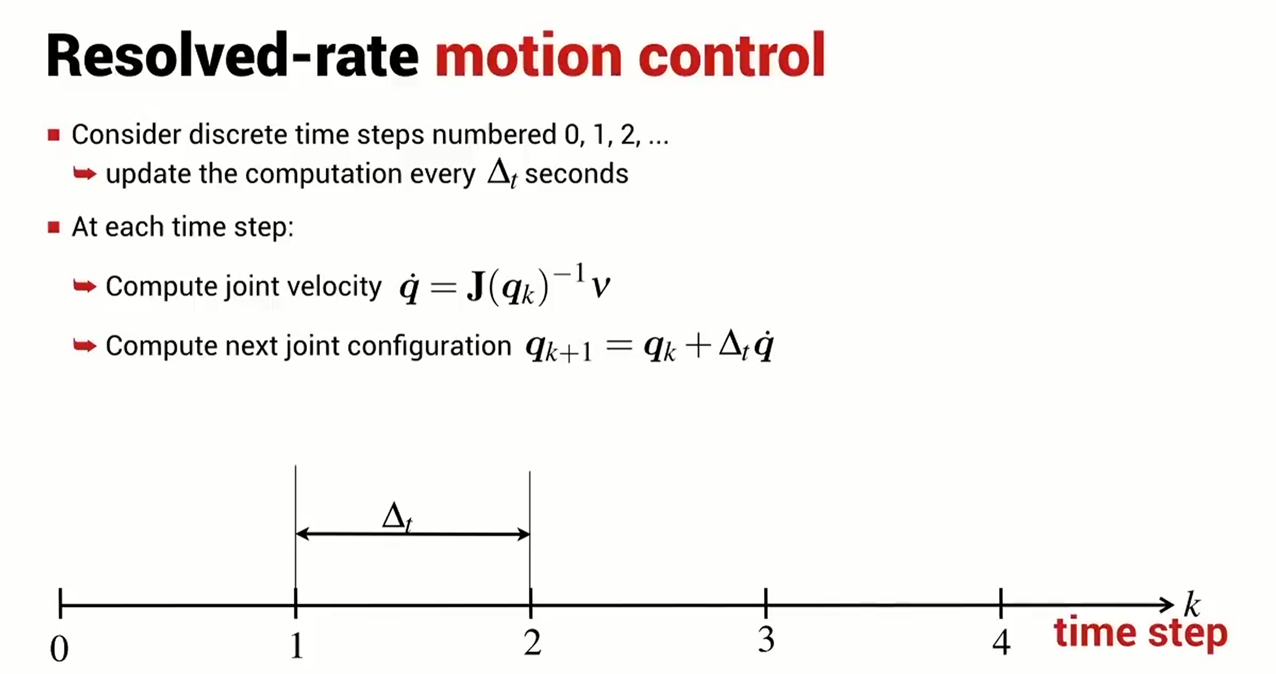

% initial pose
X = 1; Y=1; alpha = 0; 
T = transl(X,Y,0) * rpy2tr(0,0,rad2deg(alpha),'degree')

T =      1     0     0     1
     0     1     0     1
     0     0     1     0
     0     0     0     1


% target end-effetor velocity (v_x,v_y,omega)
nu = [0.1,0,0]';
% initial joint angles
q0 = p3.ikine(T,[-0.5 -0.5 alpha], 'mask',[1 1 0 0 0 1]); 

N = 20;
dt = 0.3;
q_traj = zeros(N,3);
for i=1:N
    J = p3.jacobe(q0); % 'trans', 'rot', or both ''
    q_dot = (inv(J([1,2,6],:))*nu)';  % extract the rows of J corresponding to (x,y,alpha) only, to keep it square matrix
    qk = q0+dt*q_dot;
    q_traj(i,:)= qk;
    q0 = qk;
end
disp("Ended.")

Ended.


Plot the trajectory

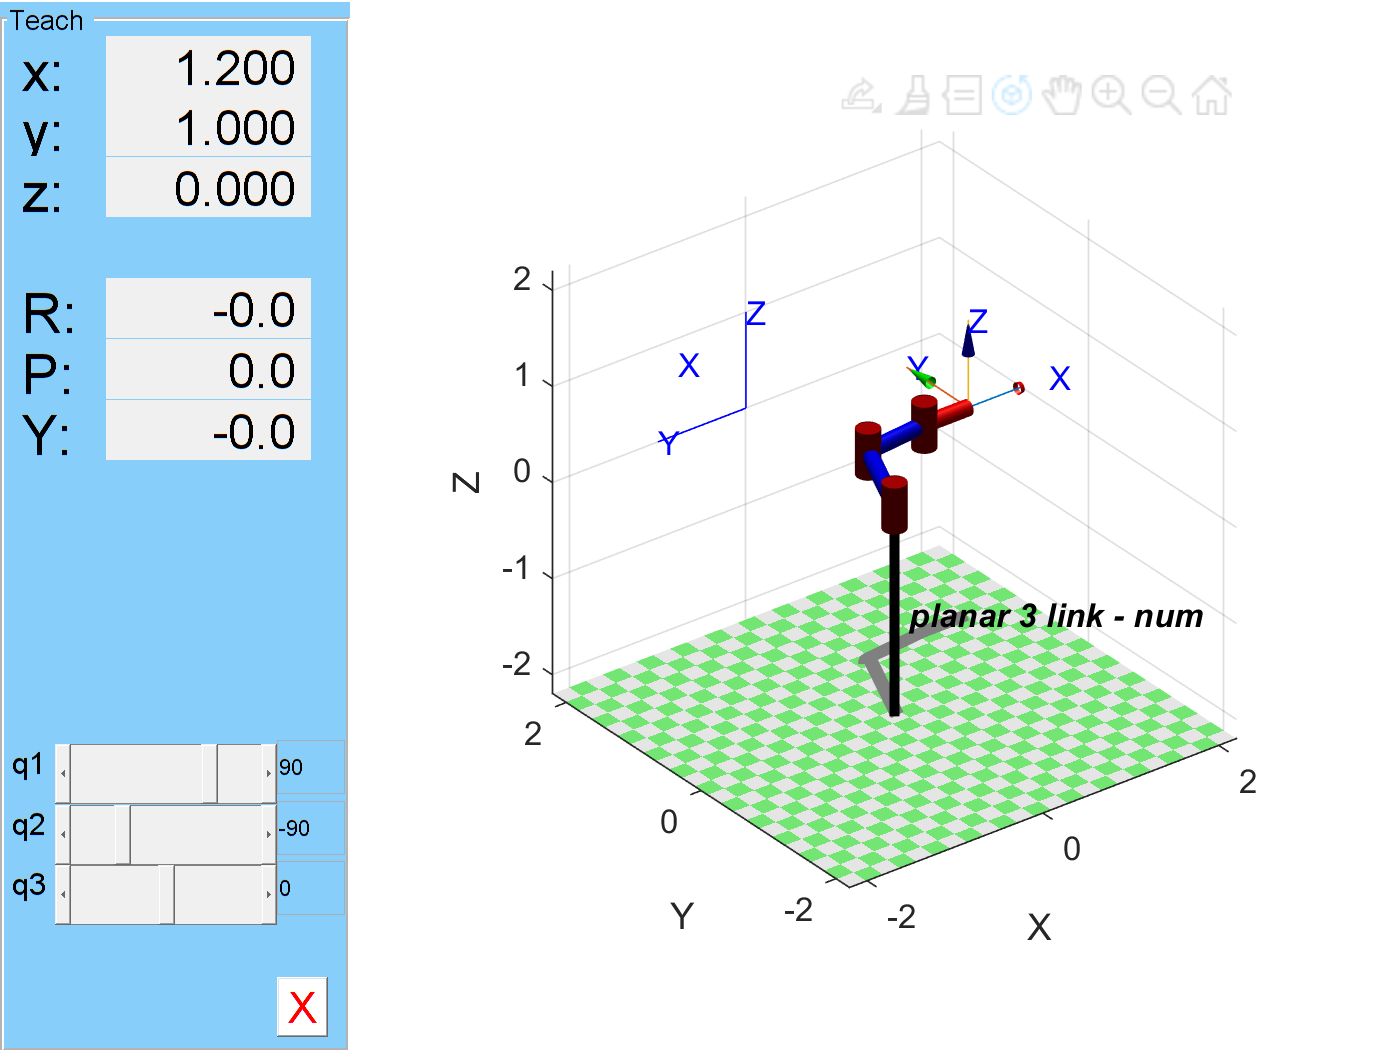

set(gcf,'Visible','on');
p3.plot(q_traj);

## **Reference commands from Robotics Toolbox:**

- **jtraj**: generate a smooth joint trajectory between two joint poses. tg = jtraj(qA,qB,50); robot.plot(tg)

- **ctraj**: generate a smooth catersian trajectory between two poses. Ts = ctraj(TA,TB,50); robot.plot(Ts)

- **qplot: **Plots the joints trajectory over time. qplot(tg)

## Additional: Example of how to get the geometric jacobian equation

a1=1; a2= 0.7; a3=0.5;
syms q1 q2 q3 
E = trchain2('R(q1) Tx(a1) R(q2) Tx(a2) R(q3) Tx(a3)',[q1,q2,q3]);
E = simplify(E)

Find Jacobian of x and y only (transational)

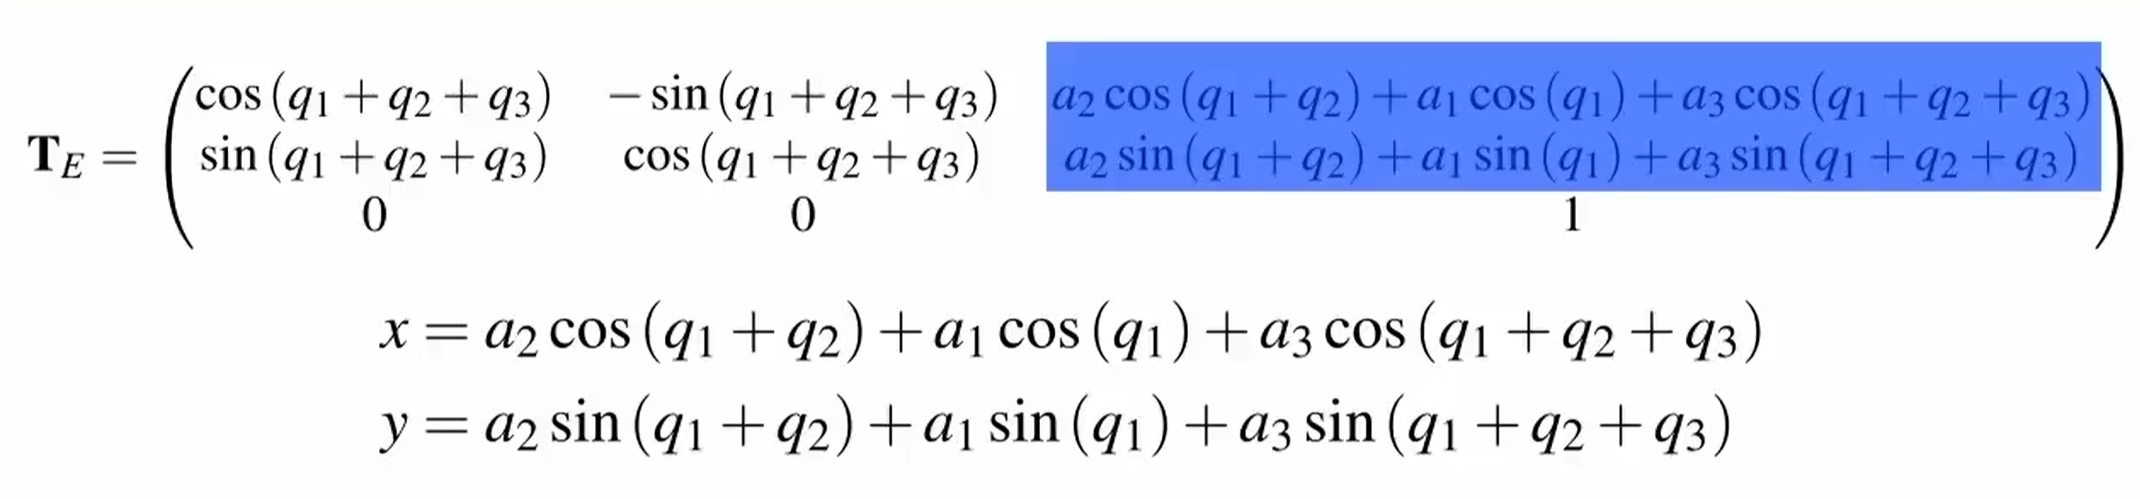

n = 3; m = 3;
J = sym('A', [n m]);
for i=1:2
    J(i,1) = diff(E(i,3),q1);

$$E = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & \frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}+\frac{7\,\cos\left(q_{1}+q_{2}\right)}{10}+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & \frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}+\frac{7\,\sin\left(q_{1}+q_{2}\right)}{10}+\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

    J(i,2) = diff(E(i,3),q2);
    J(i,3) = diff(E(i,3),q3);
   
end

Add the rotational part $\theta =\mathrm{q1}+\mathrm{q2}+\mathrm{q3};\dot{\;\theta } =\dot{\;q_{1\;} } +\dot{\;q_{2\;} } +\dot{\;q_3 }$

J(3,1) = 1;
J(3,2) = 1;
J(3,3) = 1;
simplify(J)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{1}-\frac{7\,\sin\left(q_{1}+q_{2}\right)}{10}-\sin\left(q_{1}\right) & -\sigma_{1}-\frac{7\,\sin\left(q_{1}+q_{2}\right)}{10} & -\sigma_{1}\\ \sigma_{2}+\frac{7\,\cos\left(q_{1}+q_{2}\right)}{10}+\cos\left(q_{1}\right) & \sigma_{2}+\frac{7\,\cos\left(q_{1}+q_{2}\right)}{10} & \sigma_{2}\\ 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}\\ \sigma_{2}=\frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{2} \end{array}$$

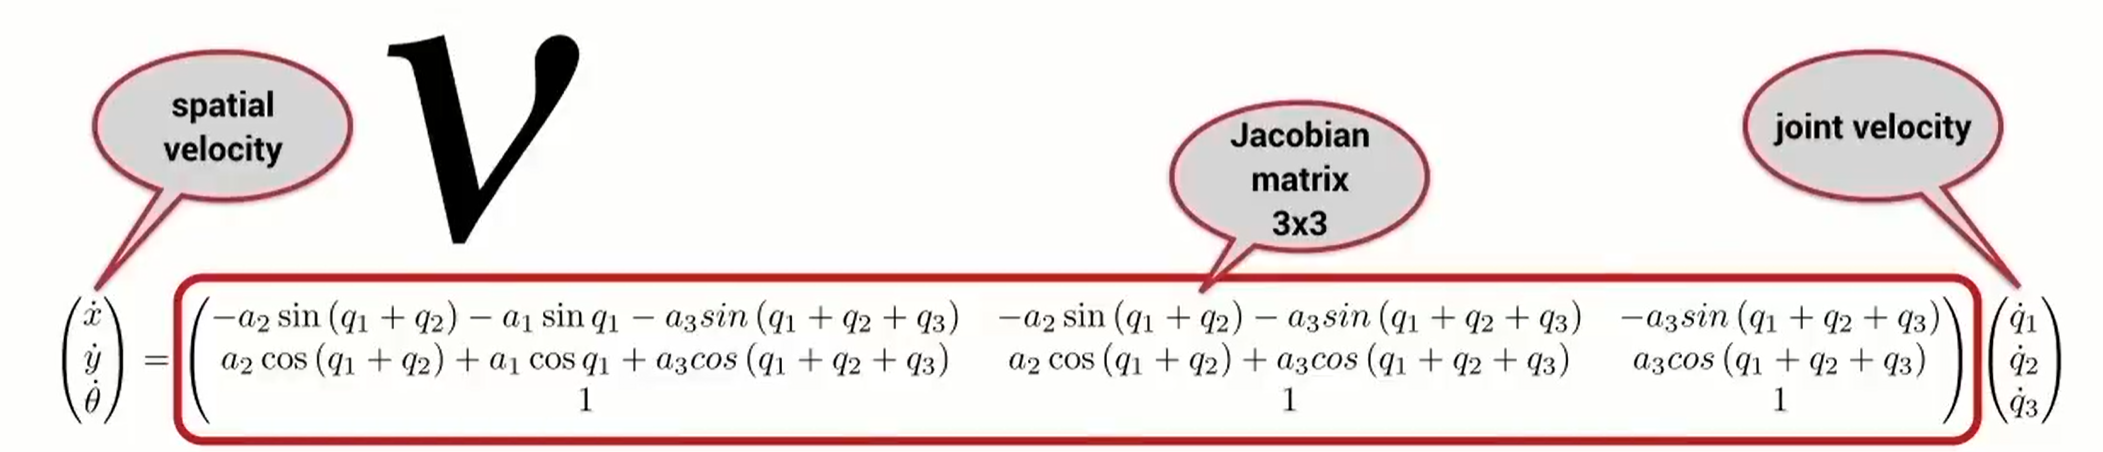

# **References**

- Robotic arms and forward kinematics course from Robot Academy [https://robotacademy.net.au/masterclass/robotic-arms-and-forward-kinematics/](https://robotacademy.net.au/masterclass/robotic-arms-and-forward-kinematics/)

- Inverse Kinematics and Robot Motion course from Robot Academy [https://robotacademy.net.au/masterclass/inverse-kinematics-and-robot-motion/](https://robotacademy.net.au/masterclass/inverse-kinematics-and-robot-motion/)

- Velocity kinematics in 2D course from Robot Academy [https://robotacademy.net.au/masterclass/velocity-kinematics-in-2d/](https://robotacademy.net.au/masterclass/velocity-kinematics-in-2d/)